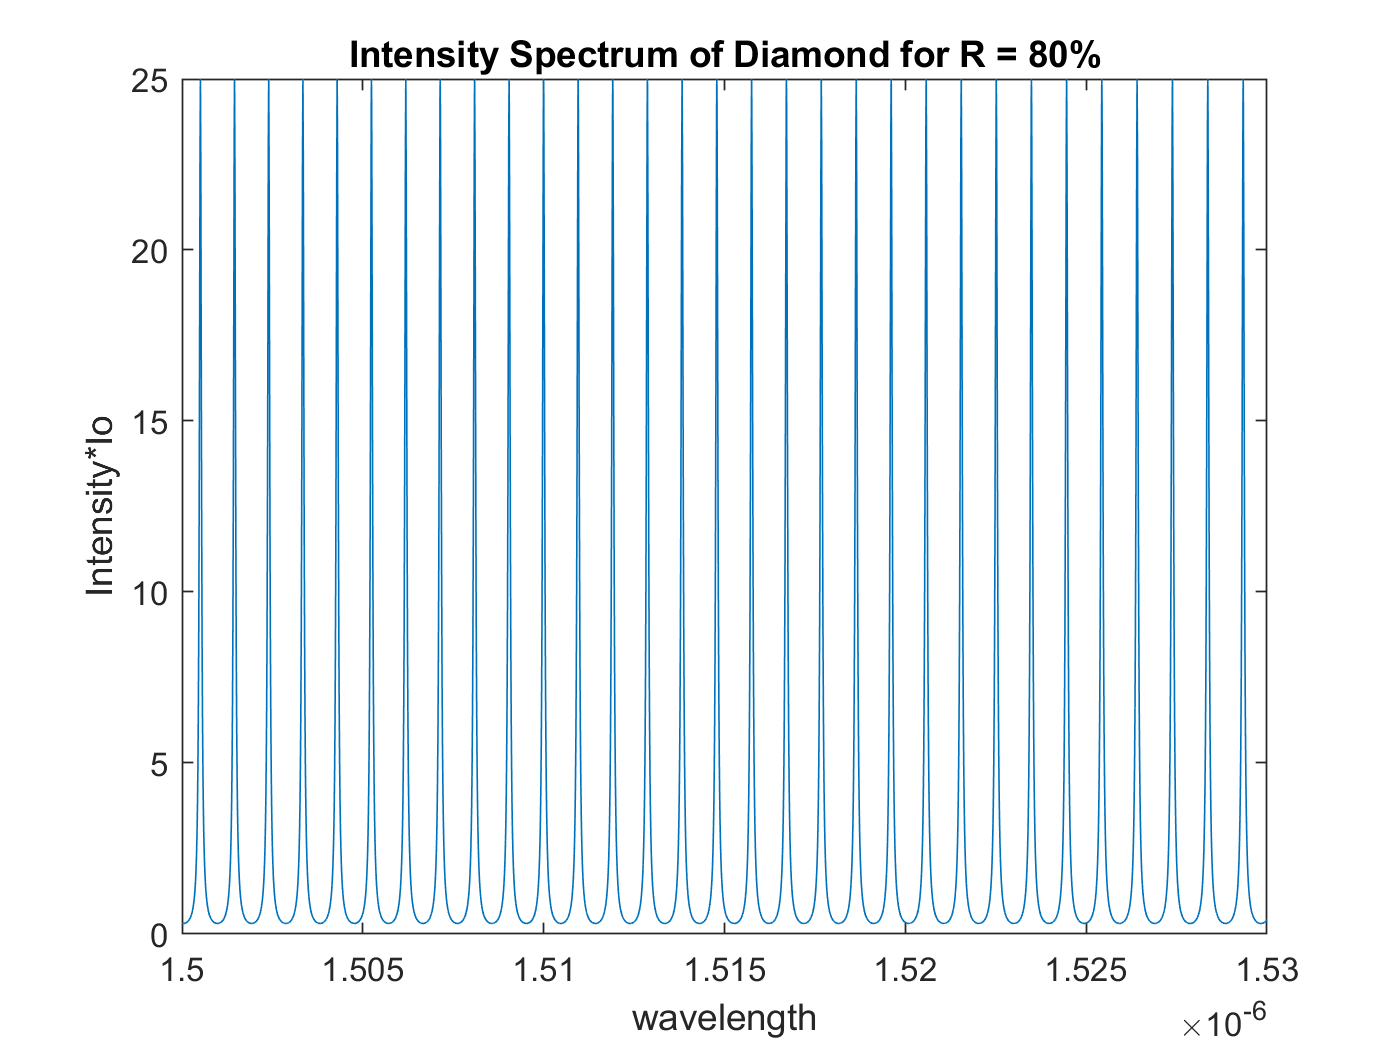

clc
clear

R = .8;
L = .5*10^(-3);
ts = .000001*10^(-6);

B1 = .3306;
B2 = 4.3356;
C1D = .175*10^(-6);
C2D = .106*10^(-6);

lambda = 1.5*10^(-6):ts:1.53*10^(-6);
n_Diamond = sqrt(1+((B1*(lambda.^2))./(lambda.^2-C1D^2))+((B2*(lambda.^2))/(lambda.^2-C2D^2)));
mpi = (2*n_Diamond.*L*pi)./lambda;

I = 1./((1-R)^2 + 4*R*sin(mpi).^2);
plot(lambda,I);
xlabel('wavelength');
ylabel('Intensity*Io');
title('Intensity Spectrum of Diamond for R = 80%');

nd = 1510*10^(-9);
n_1510 = sqrt(1+((B1*(nd^2))./(nd^2-C1D^2))+((B2*(nd^2))/(nd^2-C2D^2)));

